% ******************************************************************
% * 04/06/2021
% * Arquivo parte 1
% * Simulação de transmissão de energia eléltrica entre duas antenas 
% * Marco Tulio Masselli Rainho Teixeira
% ******************************************************************


% 1- Definindo a antena 1
r1_int = 0.4; % raio interno, 40 cm
r1_ext = 0.5; % raio externo, 50 cm
n1 = 6; % número de voltas
antena_1 = spiralArchimedean('NumArms', 1, 'Turns', n1, 'InnerRadius', r1_int, 'OuterRadius', r1_ext, 'Tilt', 90,'TiltAxis', 'Y');
figure


% 2- Encontrando a impedância e frequência de ressonância 
f = linspace(15e6,19e6,150)

f = 	1.0e+07 *

    1.5000    1.5027    1.5054    1.5081    1.5107    1.5134    1.5161    1.5188    1.5215    1.5242    1.5268    1.5295    1.5322    1.5349    1.5376    1.5403    1.5430    1.5456    1.5483    1.5510    1.5537    1.5564    1.5591    1.5617    1.5644    1.5671    1.5698    1.5725    1.5752    1.5779    1.5805    1.5832    1.5859    1.5886    1.5913    1.5940    1.5966    1.5993    1.6020    1.6047    1.6074    1.6101    1.6128    1.6154    1.6181    1.6208    1.6235    1.6262    1.6289    1.6315



z_1 = impedance(antena_1, f)

z_1 = 	1.0e+04 *

   0.0000 + 0.0451i   0.0000 + 0.0459i   0.0000 + 0.0466i   0.0000 + 0.0475i   0.0000 + 0.0483i   0.0000 + 0.0492i   0.0000 + 0.0501i   0.0000 + 0.0511i   0.0000 + 0.0522i   0.0000 + 0.0533i   0.0000 + 0.0544i   0.0000 + 0.0556i   0.0000 + 0.0570i   0.0000 + 0.0583i   0.0000 + 0.0598i   0.0000 + 0.0614i   0.0000 + 0.0631i   0.0000 + 0.0649i   0.0000 + 0.0669i   0.0000 + 0.0690i   0.0000 + 0.0713i   0.0000 + 0.0738i   0.0000 + 0.0765i   0.0000 + 0.0795i   0.0000 + 0.0828i   0.0000 + 0.0865i   0.0000 + 0.0906i   0.0000 + 0.0951i   0.0000 + 0.1003i   0.0000 + 0.1062i   0.0000 + 0.1130i   0.0000 + 0.1209i   0.0000 + 0.1301i   0.0000 + 0.1412i   0.0000 + 0.1547i   0.0001 + 0.1715i   0.0001 + 0.1930i   0.0001 + 0.2213i   0.0001 + 0.2607i   0.0002 + 0.3187i   0.0004 + 0.4134i   0.0008 + 0.5947i   0.0028 + 1.0837i   0.1248 + 7.0296i   0.0060 - 1.5118i   0.0012 - 0.6713i   0.0005 - 0.4267i   0.0003 - 0.3101i   0.0002 - 0.2419i   0.0001 - 0.1971i


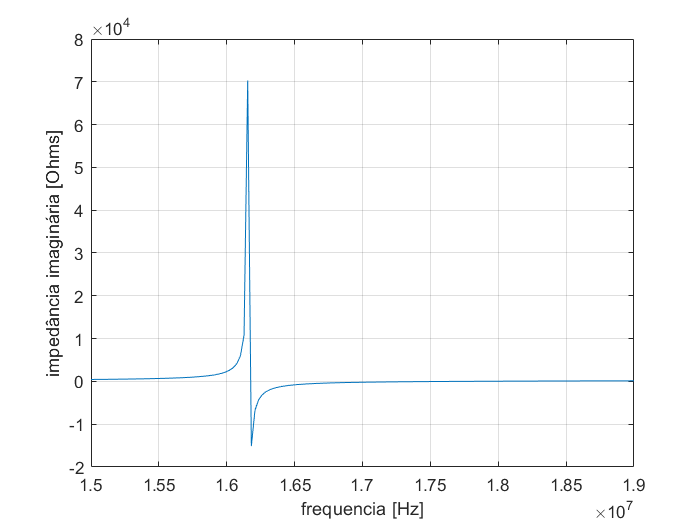

plot(f, imag(z_1))
grid on
xlabel('frequencia [Hz]')
ylabel('impedância imaginária [Ohms]')


% valor de frequência que resulta numa impedância com imaginário nulo, para achar a frequência de ressonanssia
imag(impedance(antena_1, 17.68e6))

ans = -1.7592


% f de ressonancia 17.68 MHz (observado no gráfico, conferido pelo valor encontrado na linha anterior)
% f critica 1.615 MHz (observado no gráfico)
f_ress = 17.68e6

f_ress = 17680000

fc = 16.15e6

fc = 16150000

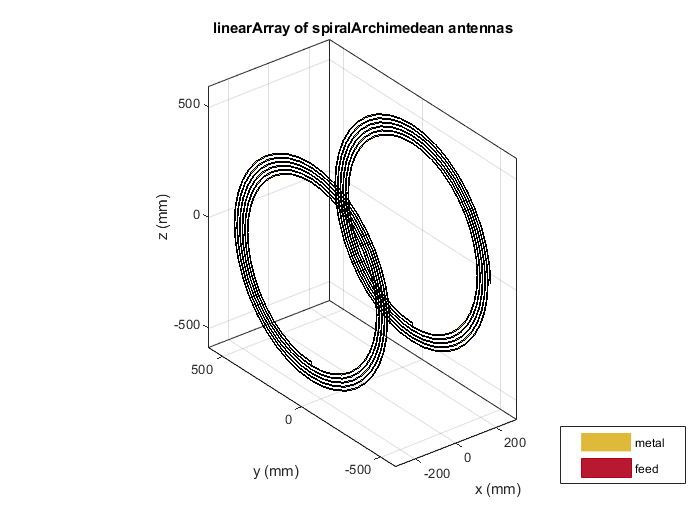



% 3- Definindo a antena 2
r2_int = 0.4; % raio interno, 40 cm
r2_ext = 0.5; % raio externo, 50 cm
n2 = 6; % número de voltas
antena_2 = spiralArchimedean('NumArms', 1, 'Turns', n2, 'InnerRadius', r2_int, 'OuterRadius', r2_ext, 'Tilt', 90,'TiltAxis', 'Y');

% colocando as antenas no mesmo espaço virtual
la=linearArray('Element', [antena_1, antena_1], 'ElementSpacing', 0.5); 
show(la)

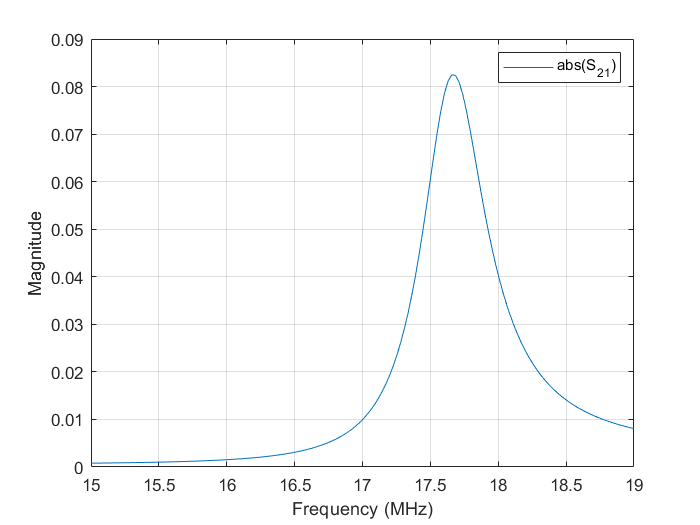



% 4- Obtenção do ganho entre as antenas  
ganhos = sparameters(la, f);


% 5- Visualização do ganho 
rfplot(ganhos,2,1, 'abs')

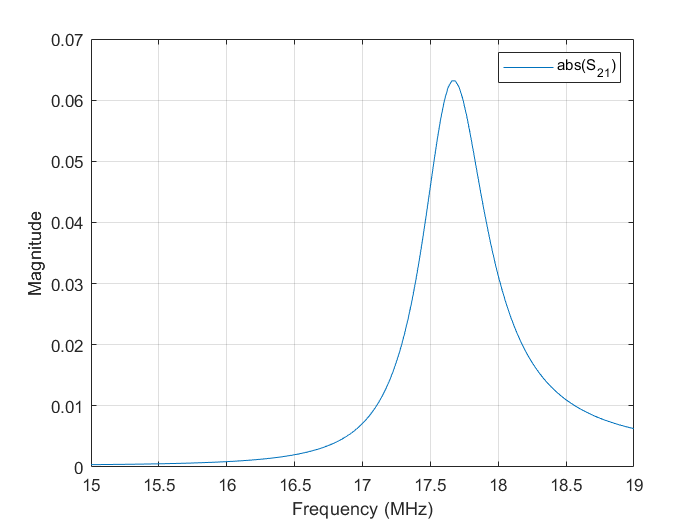


% Percebemos aqui que a frequência de maior ganho coincide com a frequência de ressonância encontrada no item 2

% 6- Visualização do ganho em funcao da frequencia e da distancia

dist = linspace(0.05, 0.6, 10); % distância, 5 a 60 cm
m = zeros(10,150); % matriz de ganhos

% o loop a seguir nos permite calcular os ganhos das antenas, em função da frequência e distância entre elas.
for j = 1: length(dist)
    la_var = linearArray('Element', [antena_1, antena_1], 'ElementSpacing', dist(j));
    param_var = sparameters(la_var, f);
    ganhos_freq_var = rfplot(param_var,2,1,'abs');
    ganhos_array = ganhos_freq_var.YData;
    m(j,:) = ganhos_array;
end

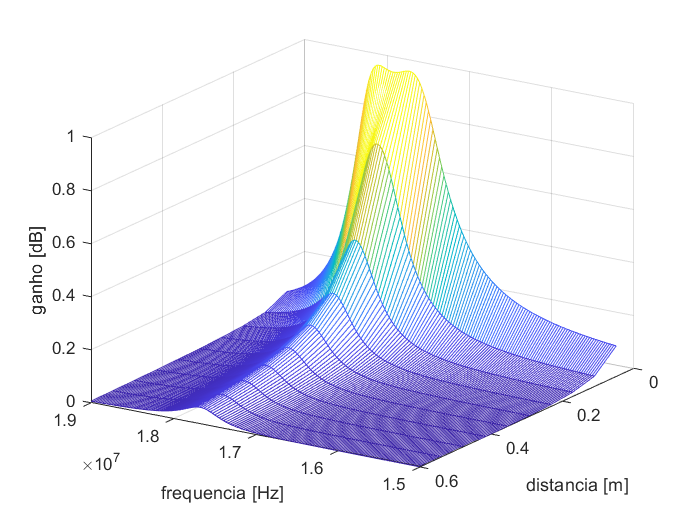


% plotando o gráfico 3D
mesh(f, dist, m)
xlabel('frequencia [Hz]')
ylabel('distancia [m]')
zlabel('ganho [dB]')

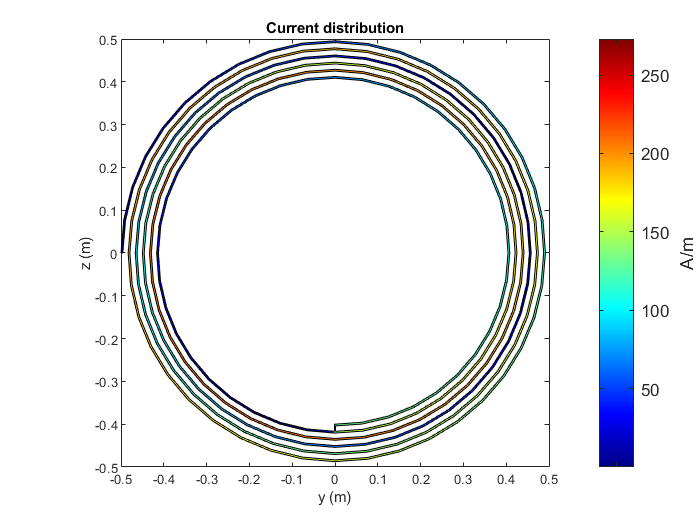



% 7- Corrente ressonante
current(antena_1, f_ress)

% Esse item não pode ser bem aproveitado pelo grupo, já que temos a versão 2020 do MatLab e nosso condutor da antena é quase ideal. Mesmo assim, é
% possível perceber a diferença nas tonalidades da espira, mesmo que a corrente seja altíssima pela resistência quase nula do metal.

% 8- Unindo os modelos
sigma = 24 % O sigma foi encontrado com base em testes de diversos valores, e esse foi o que mais combinou nas frequências crítica e de ressonância.

sigma = 24

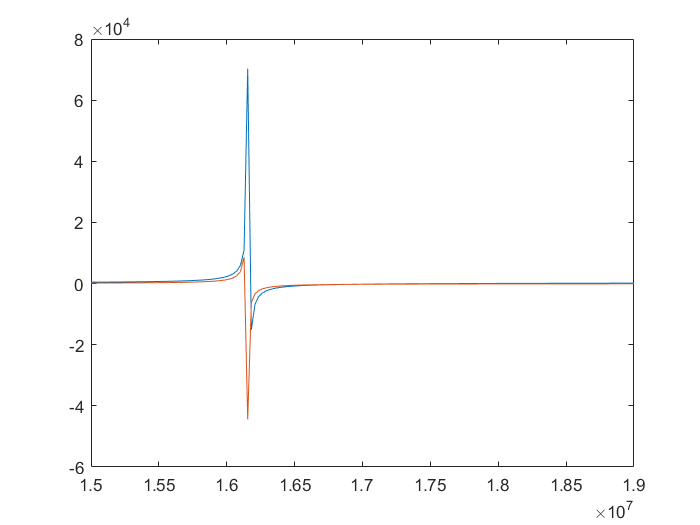

z_list = [];

% temos aqui uma lista de impedâncias para cada frequência no intervalo estudado, pelo modelo baseado no de um transformador
for n = 1: length(f)
    z_list(n) = sigma^2/(1i*f(n)*sigma/fc + fc*sigma/(1i*f(n))) + 4*f(n)*sigma/fc;
end

plot(f, imag(z_1), f, imag(z_list))

xlabel('frequencia [Hz]')
ylabel('impedância imaginária [Ohms]')
% em azul,a impedância da antena, em vermelho, o modelo de transformador

% Relacionar Mútua com distância
dist = linspace(0.05, 0.6, 50); % 5 a 60 cm

%lista de ganhos na frequência de ressonância para diversas distâncias
ganhos_f_ress = zeros(1,50);
for j = 1: length(dist)
    la_var = linearArray('Element', [antena_1, antena_1], 'ElementSpacing', dist(j));
    param_var = sparameters(la_var, f_ress);
    ganhos_freq_var = rfplot(param_var,2,1,'abs');
    ganhos_array = ganhos_freq_var.YData;
    ganhos_f_ress(1,j) = ganhos_array;
end


% Plotando o gráfico de indutância mútua por distância
hold off
Rc = 1

Rc = 1

M = Rc*(ganhos_f_ress).^(1/2)/(f_ress*2*pi())

M = 	1.0e+-8 *

    0.8933    0.8987    0.8940    0.8689    0.8353    0.7967    0.7567    0.7174    0.6800    0.6452    0.6130    0.5834    0.5564    0.5317    0.5091    0.4884    0.4694    0.4520    0.4360    0.4212    0.4075    0.3948    0.3830    0.3721    0.3619    0.3523    0.3434    0.3350    0.3271    0.3196    0.3126    0.3060    0.2997    0.2937    0.2880    0.2826    0.2774    0.2725    0.2678    0.2632    0.2589    0.2547    0.2507    0.2469    0.2432    0.2396    0.2361    0.2327    0.2295    0.2263


% Modelo: M = ( Rc * sqrt(G) ) / ( 2 * pi * f )
plot(dist, M)
ylabel('Indutância mútua [H]')
xlabel('Distancia [m]')


